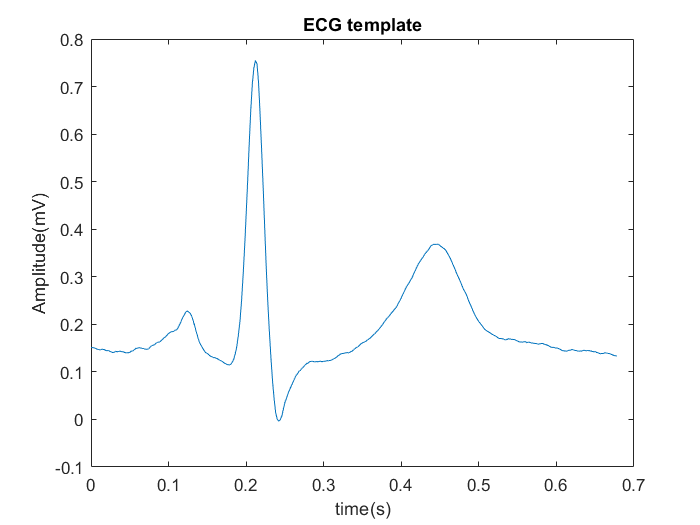

load ECG_template.mat;
t =(0:length(ECG_template)-1)/500;
plot(t,ECG_template);
title('ECG template');
xlabel('time(s)')
ylabel('Amplitude(mV)')

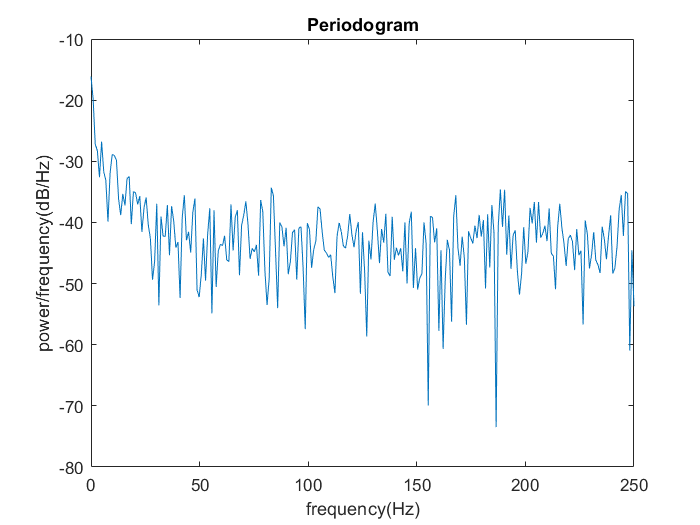

nECG=awgn(ECG_template,5,'measured');
[pxx,f]=periodogram(nECG,[],[],500);
plot(f,10*log10(pxx))
xlabel('frequency(Hz)');
ylabel('power/frequency(dB/Hz)');
title('Periodogram');

new_signal=[0,0 nECG];
ma3ECG_1=ones(1,length(nECG));
for r=3:length(new_signal)
    ma3ECG_1(r-2) = sum(new_signal(r-2:r))/3;
end


Group delay = 2/2 = 1

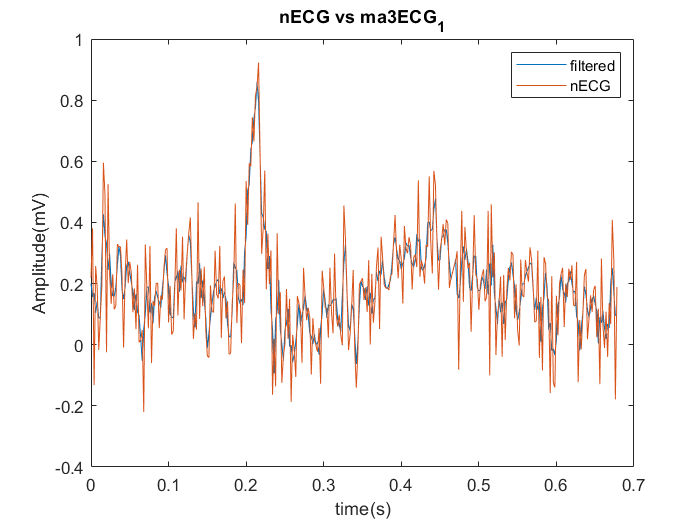

compensated_signal=[ma3ECG_1(2:end) ma3ECG_1(end) ];
plot(t,compensated_signal)
hold on;
plot(t,nECG)
hold off;
title('nECG vs ma3ECG_1');
xlabel('time(s)')
ylabel('Amplitude(mV)')
legend('filtered','nECG')

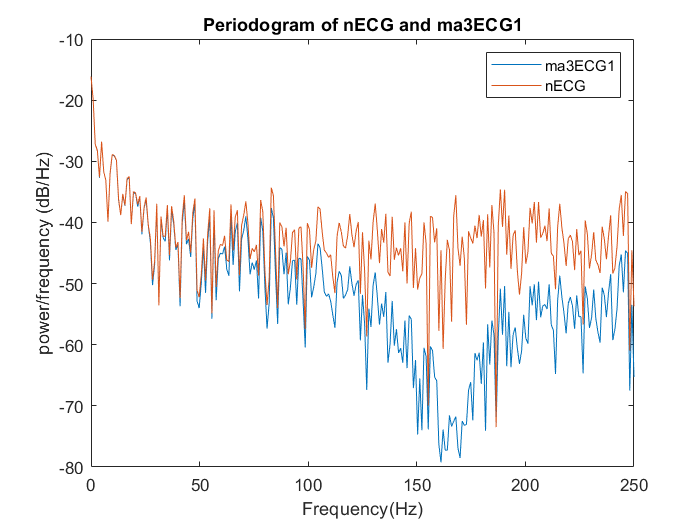

[pxx1,f1]=periodogram(ma3ECG_1,[],[],500);
plot(f1,10*log10(pxx1),f,10*log10(pxx))
title('Periodogram of nECG and ma3ECG1')
xlabel('Frequency(Hz)')
ylabel('power/frequency (dB/Hz)')
legend('ma3ECG1','nECG')

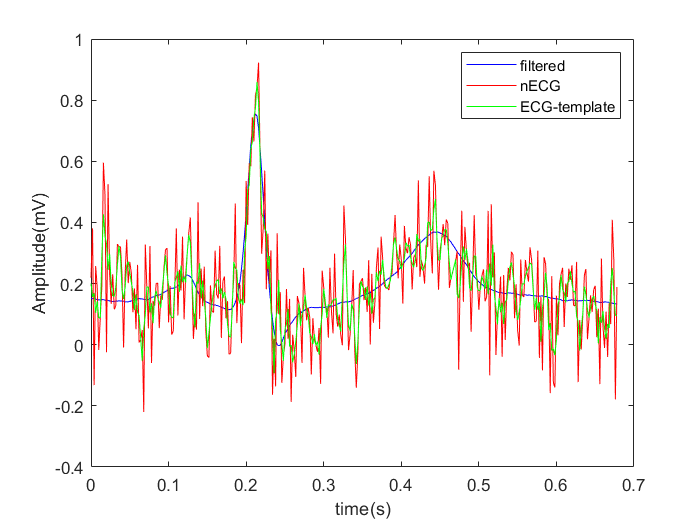

b=ones(1,3)*(1/3);
ma3ECG_2=filter(b,(1),nECG);
plot(t,ECG_template,'b')
hold on;
plot(t,nECG,'r')
plot(t,compensated_signal,'g')
hold off;
xlabel('time(s)')
ylabel('Amplitude(mV)')
legend('filtered','nECG','ECG-template')

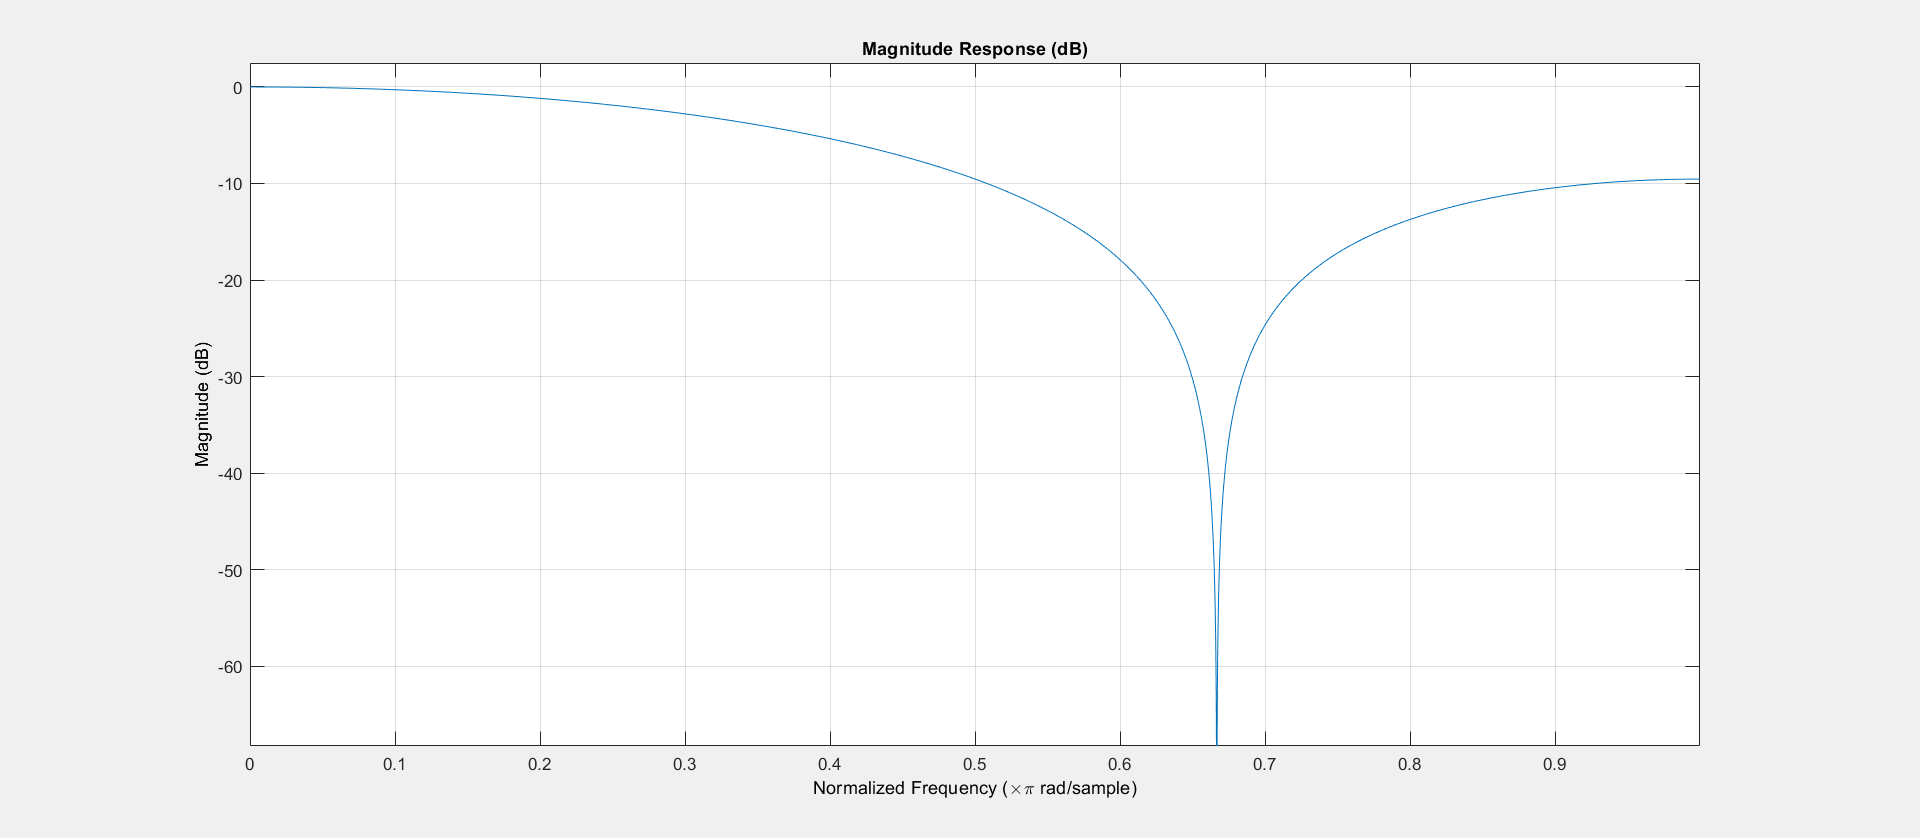

fvtool(b,1)

b=ones(1,10).*0.1;

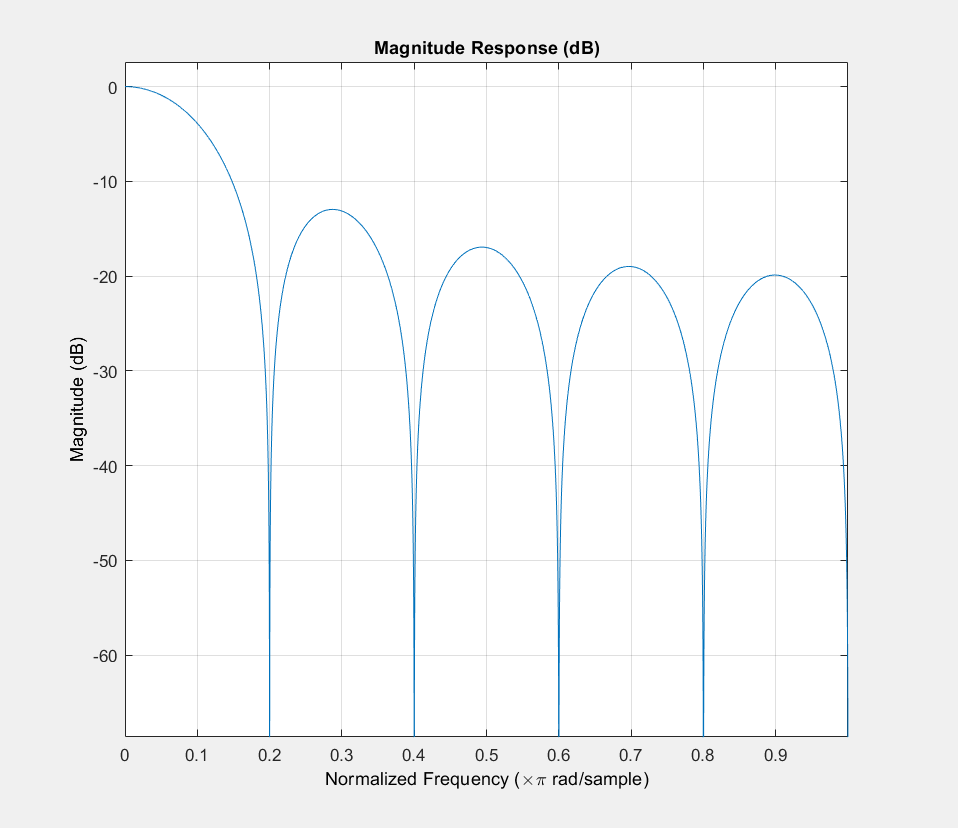

fvtool(b,(1))

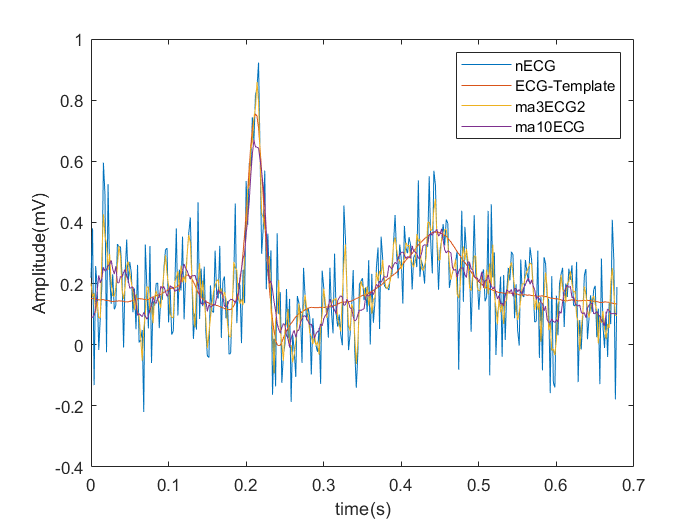

ma10ECG=filter(b,(1),nECG);
plot(t,nECG)
hold on;
plot(t,ECG_template)
plot(t,compensated_signal)
plot(t,[ma10ECG(5:end) ones(1,4)*ma10ECG(1,end)])
hold off;
xlabel('time(s)')
ylabel('Amplitude(mV)')
legend('nECG','ECG-Template','ma3ECG2','ma10ECG');

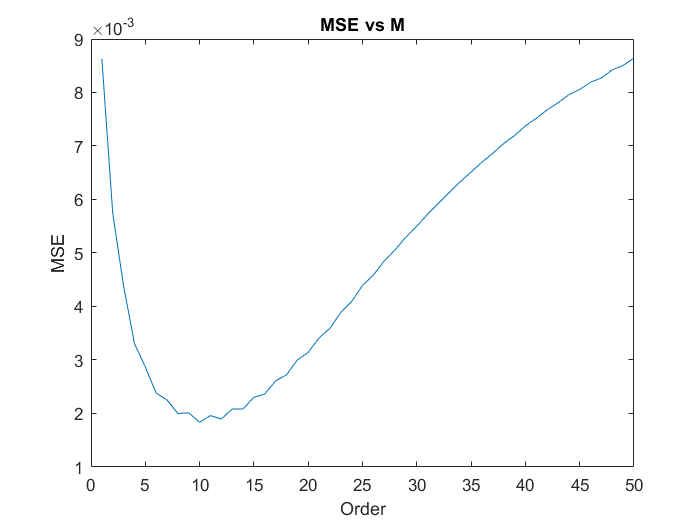

MSE_vals=zeros(1,50);
for N=1:50
    MSE_vals(N)=CalcMSE(N,nECG,ECG_template);
end

plot(MSE_vals)
title('MSE vs M')
xlabel('Order')
ylabel('MSE')

min_M=find(MSE_vals==min(MSE_vals));

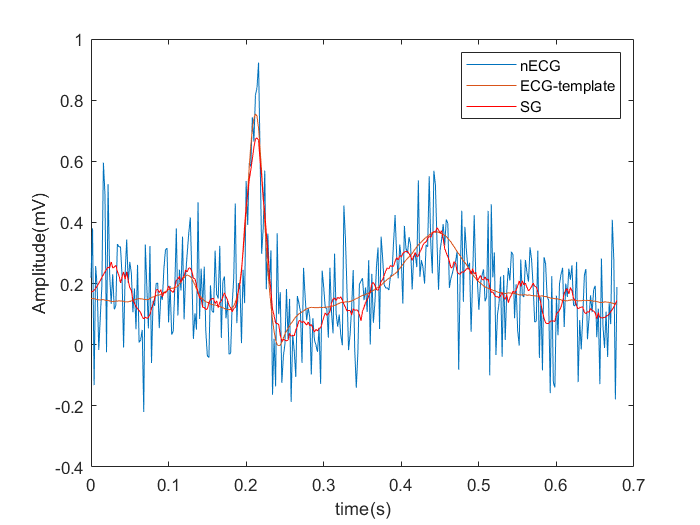

sg310ECG=sgolayfilt(nECG,3,23);
plot(t, nECG)
hold on;
plot(t, ECG_template)
plot(t,sg310ECG,'r')
hold off;
xlabel('time(s)')
ylabel('Amplitude(mV)')
legend('nECG','ECG-template','SG')

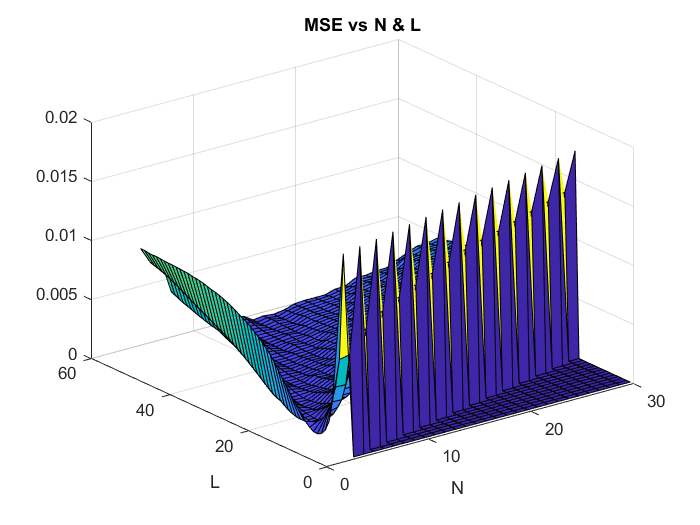

N_limit=30;
L_limit=50;
SGMSE_values=zeros(L_limit,N_limit);
[N,L]=meshgrid(1:N_limit,1:L_limit);

min_val=1;
coord=[0,0];
for n=1:N_limit
    for l=1:L_limit
        if n<=2*l
            val=CalcSGMSE(n,l,nECG,ECG_template);
            SGMSE_values(l,n)=val;
            if val<min_val
                min_val=val;
                coord=[n,l];
            end
        end
    end
end

surf(N,L,SGMSE_values)
title('MSE vs N & L');
xlabel('N')
ylabel('L')

min_N=coord(1);
min_L=coord(2);

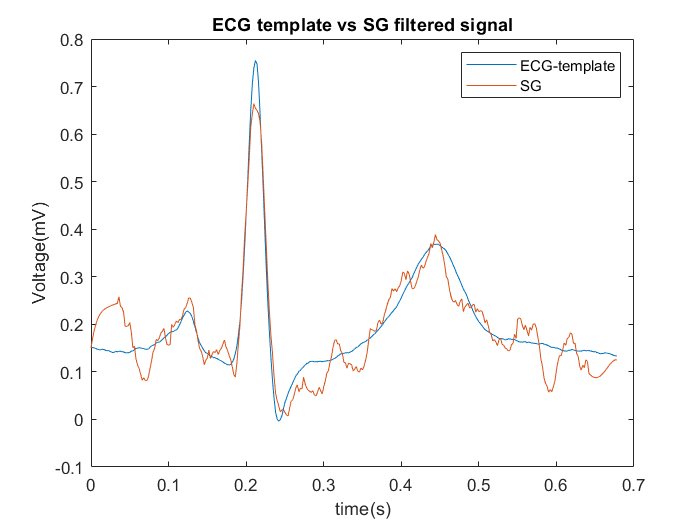

sg310ECG=sgolayfilt(nECG,min_N,2*min_L+1);
plot(t,ECG_template)
hold on;
plot(t,sg310ECG)
hold off;
title('ECG template vs SG filtered signal');
xlabel('time(s)')
ylabel('Voltage(mV)')
legend('ECG-template','SG')

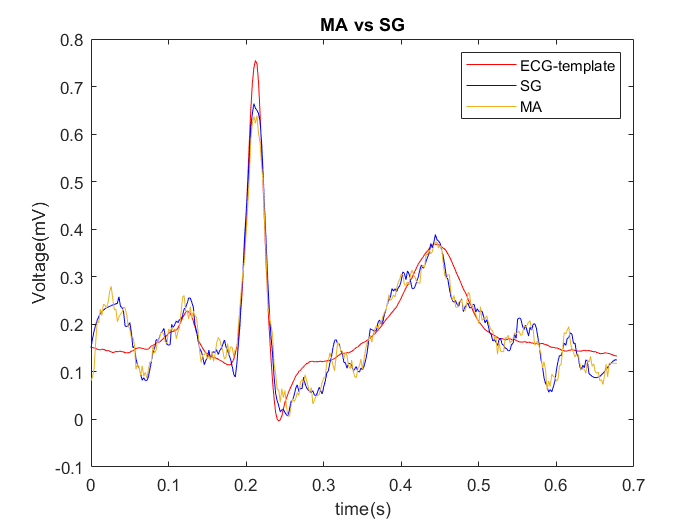

plot(t,ECG_template,'r')
hold on;
plot(t,sg310ECG,'b')
new_fSig=filter(ones(1,min_M+1)./(min_M+1),1,nECG);
new_fSig=[new_fSig(floor(min_M/2)+1:end), ones(1,floor(min_M/2))*new_fSig(end)];
plot(t,new_fSig)
hold off;
title('MA vs SG');
xlabel('time(s)')
ylabel('Voltage(mV)')
legend('ECG-template','SG','MA')

function MSE=CalcMSE(N,nECG,ECG_template)
    b=ones(1,N+1)*(1/(N+1));
    filtered=filter(b,(1),nECG);
    g_delay=floor(N/2);
    filtered=[filtered(g_delay+1:end), ones(1,g_delay).*filtered(end)];
    MSE=sum(((filtered-ECG_template).^2))/length(ECG_template);
end

function SGMSE=CalcSGMSE(N,L,nECG,ECG_template)
    filtered1=sgolayfilt(nECG,N,2*L+1);
    SGMSE=sum(((filtered1-ECG_template).^2))/length(ECG_template);
end